
%Coefficients of Objective Function
Z = [2 1];

LPP_Type = "max";


%Store the Coefficient Matrix (Ax = b)
A = [1 , 2; 1 1; 1 -1; 1 -2;1 0; 0 1];

A =      1     2
     1     1
     1    -1
     1    -2
     1     0
     0     1


%Constraints on x1 and x2
%x1>0
%x2>0
%Here I have add last two constraints because of non-negative constraint

%Store the values of the RHS of Inequalities
b = [10 ;6; 2; 1;0;0]

b =     10
     6
     2
     1
     0
     0


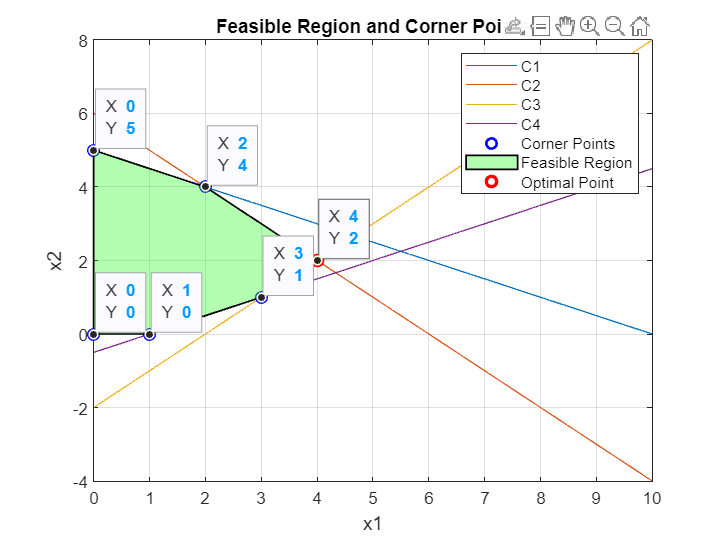



x1_vals = linspace(0,10);

%Now make equations in terms of x1_vals
x2_c1 = (((-A(1,1) * x1_vals) + b(1) )/ A(1,2));

x2_c2 = (((-A(2,1) * x1_vals) + b(2) )/ A(2,2));

x2_c3 = (((-A(3,1) * x1_vals) + b(3) )/ A(3,2));

x2_c4 = (((-A(4,1) * x1_vals) + b(4) )/ A(4,2));



%x2_c1 = max(0,x2_c1);
% x2_c2 = max(0,x2_c2);
% x2_c3 = max(0,x2_c3);
% x2_c4 = max(0,x2_c4);


%Find all the intersection point between all the lines

HG = [0;0];

for i=1:size(A,1)
    hg1 = A(i,:);
    b1=b(i,:);
    for j=i+1:size(A,1)
        hg2 = A(j,:);
        b2 = b(j,:);
        Aa = [hg1;hg2];
        Bb = [b1;b2];
        Xx = Aa\Bb;
        HG = [HG Xx];
    end
end

%Store all the intersection points in another variable
all_points = HG';

%Keep the unique points only
all_points = unique(all_points,'rows');

%Find The Corner_Points from the all points by passing it to the
%constraints function

%Constraints Function will check and keep only those points who satisfy all
%the constraints
corner_points = constraints(all_points);


%Keep in mind that you have to edit the constraints function according to
%the LPP

%If the LPP is max 
if LPP_Type == "max"
    optimal_soln = findmaxof(corner_points,z);
else
    optimal_soln = findminof(corner_points,z);
end

%Store the optimal points and value in different variables
optimal_points = [corner_points(optimal_soln(1,1),1) corner_points(optimal_soln(1,1),2)];

optimal_value = optimal_soln(2);


%Plot the constraint lines
plot(x1_vals,x2_c1, x1_vals,x2_c2 ,x1_vals,x2_c3 ,x1_vals,x2_c4);
xlabel("x1");
ylabel("x2");
title("Feasible Region and Corner Points");
hold on;

%Scatter All The Corner Points of the Feasible Region
s = scatter(corner_points(:,1),corner_points(:,2),'blue',LineWidth=1.5);

 
% Calculate the convex hull of corner points
k = convhull(corner_points(:, 1), corner_points(:, 2));
    
% Create a polygon from convex hull points and fill it with color
F_reegion = fill(corner_points(k, 1), corner_points(k, 2), 'green', 'FaceAlpha', 0.3,EdgeColor='black',LineWidth=1);

%Scatter the Optimal Point With Filled RED color
opti_pt = scatter(optimal_points(1,1),optimal_points(1,2),MarkerEdgeColor='r',LineWidth=2);
grid on;

%Show the Co-ordinates of the corner points
for i=1:size(corner_points,1)
    datatip(s,corner_points(i,1),corner_points(i,2));
end
legend(["C1","C2","C3","C4","Corner Points","Feasible Region","Optimal Point"])

function out = findmaxof(cp,Z)  %Function To Find the maximum value of the objective function
    indx = 0;
    ansr = 0;
    for i=1 : size(cp,1)
        calc = cp(i,1)*Z(1,1) + cp(i,2)*Z(1,2);
        if calc > ansr
            ansr = calc;
            indx = i;
        end
    end

    out = [indx ansr];
   

end


%Function To Find the minimum value of the objective function

function out = findminof(cp,Z)
    iterator = 0;
    ansr = 0;
    for i=1 : size(cp,1)
        calc = cp(i,1)*Z(1,1) + cp(i,2)*Z(1,2);
        if calc <= ansr
            ansr = calc;
            iterator = i;
        end
    end

    out = [iterator ansr];
end


%Function to validate the intersection points
%Separating all the points who satisfy all the constraints

function out = constraints(points)

    x1 = points(:,1);
    x2 = points(:,2);
    cons1 = x1 + 2*x2 - 10;
    remove_pts = cons1>0;
    points(remove_pts,:)=[];


     x1 = points(:,1);
    x2 = points(:,2);
    cons2 = x1 + x2- 6;
    remove_pts = cons2>0;
    points(remove_pts,:)=[];


     x1 = points(:,1);
    x2 = points(:,2);
    cons3 = x1 - x2 - 2;
    remove_pts = cons3>0;
    points(remove_pts,:)=[];


     x1 = points(:,1);
    x2 = points(:,2);
    cons4 = x1 - 2*x2 - 1;
    remove_pts = cons4>0;
    points(remove_pts,:)=[];

         x1 = points(:,1);
    x2 = points(:,2);
    cons5 = x1;
    remove_pts = cons5<0;
    points(remove_pts,:)=[];


    x1 = points(:,1);
    x2 = points(:,2);
    cons6 = x2;
    remove_pts = cons6<0;
    points(remove_pts,:)=[];

    out = points;
end

